%Funktion til at lave map direkte i Matlab
%homemade_map = makemap(80); 
%Create connection in MATLAB
% assuming the Turtlebot ip is 192.168.106.186
setenv('ROS_MASTER_URI','http://192.168.6.191:11311')

% assuming your own ip-(host) is 192.168.75.164
setenv('ROS_IP','192.168.6.155')
rosinit('http://192.168.6.191:11311','NodeHost','192.168.6.155');

Initializing global node /matlab_global_node_23377 with NodeURI http://192.168.6.155:64336/


%importer map
% Load the image
img = imread('C:\Users\frede\OneDrive\Dokumenter\6_semester\ANS\projekt\Testmap1.png');


% Convert the image to grayscale
gray_img = rgb2gray(img);

% Convert the grayscale image to a binary image
binary_img = imbinarize(gray_img)

binary_img = 1010×1012 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   


% Create a binary occupancy map from the binary image
map = binaryOccupancyMap(binary_img, 5)

map =   binaryOccupancyMap with properties:

    GridLocationInWorld: [0 0]
           XWorldLimits: [0 202.4000]
           YWorldLimits: [0 202]
               DataType: 'logical'
           DefaultValue: 0
             Resolution: 5
               GridSize: [1010 1012]
           XLocalLimits: [0 202.4000]
           YLocalLimits: [0 202]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]



% Resize the map to be 10 times larger
scale_factor = 1/250;
resized_map = imresize(map.occupancyMatrix);

Error using imresize>fixupSizeAndScale (line 713)
Either scale or output size must be specified.

Error in imresize>parseInputs (line 297)
params = fixupSizeAndScale(params);

Error in imresize (<a hr


% Create a new binary occupancy map from the resized matrix
new_map = binaryOccupancyMap(resized_map);

% Show the map
show(new_map);

%map = makemap(20);
%map = flip(map,1);
%map = binaryOccupancyMap(map);
%show(map);

robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

scaleFactor = 1/4;
% Scale the map
mapScaled = imresize(map.occupancyMatrix, scaleFactor)

mapScaled = 253×253 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  


mapInflated = copy(mapScaled);

Check for missing argument or incorrect argument data type in call to function 'copy'.

inflate(mapInflated, robot.TrackWidth/2);
prm = robotics.PRM(mapInflated);
prm.NumNodes = 300;
prm.ConnectionDistance = 150;
show(prm)



startLocation = [900, 100];
endLocation = [900, 900];
path1 = findpath(prm, startLocation, endLocation)

path1 =   900.0000  100.0000
  934.8745  112.7446
  800.5582  124.8087
  654.7009  122.0416
  515.1552  108.7587
  437.4514  104.6995
  335.1944  116.4197
  215.2496  130.0644
  139.2324  119.6546
  136.2837  179.3831



path = path1 - startLocation

path =          0         0
   34.8745   12.7446
  -99.4418   24.8087
 -245.2991   22.0416
 -384.8448    8.7587
 -462.5486    4.6995
 -564.8056   16.4197
 -684.7504   30.0644
 -760.7676   19.6546
 -763.7163   79.3831


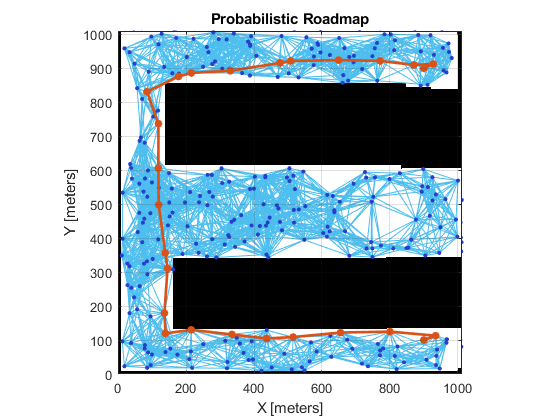

show(prm);


robotInitialLocation = path(1,:)

robotInitialLocation =      0     0


robotGoal = path(end,:)

robotGoal =      0   800


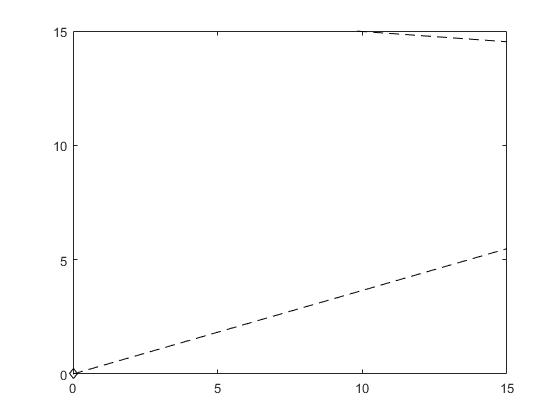


initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';
robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");


figure
plot(path(:,1), path(:,2),'k--d')
xlim([-0 15])
ylim([-0 15])


controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 1;
controller.LookaheadDistance = 0.5;

goalRadius = 0.2;
distanceToGoal = norm(robotInitialLocation - robotGoal);

**Kommando til at køre selve turtlebot**



% TIL TURTLEBOT - DEFINITIVT!
vel_pub = rospublisher('/cmd_vel');
velmsg = rosmessage(vel_pub);
odomSub = rossubscriber("/odom","DataFormat","struct");

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;
s = path(1,:)

s =      0     0


current_pose = robotCurrentPose

current_pose =      0
     0
     0



r_pose = receive(odomSub);

init_position = [r_pose.pose.pose.position.x r_pose.pose.pose.position.y]
r_init_orientation = [r_pose.pose.pose.orientation.x r_pose.pose.pose.orientation.y r_pose.pose.pose.orientation.z r_pose.pose.pose.orientation.w]

eul = quat2eul(r_init_orientation);
init_orientation = eul(3);
init_pose = [init_position init_orientation]';

theta = eul(3);
rot_mat = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    velmsg.Angular.Z = omega;	% Angular velocity (rad/s)
    velmsg.Linear.X = v;
    send(vel_pub,velmsg);

    
    % Get the robot's velocity using controller inputs
    r_pose = receive(odomSub);
    position_x = r_pose.pose.pose.position.x;
    position_y = r_pose.pose.pose.position.y;
    position = [position_x position_y];
    x = r_pose.pose.pose.orientation.x;
    y = r_pose.pose.pose.orientation.y;
    z = r_pose.pose.pose.orientation.z;
    w = r_pose.pose.pose.orientation.w;
    eul = quat2eul([x y z w]);
    orientation = eul(3);
    
    
    robotCurrentPose = [position orientation]' - init_pose;
    %vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    %robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    s(end+1,:) = robotCurrentPose(1:2);
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
  
    plot(path(:,1), path(:,2),"k--d")
    hold all
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([-15 15])
    ylim([-15 15])
    
    waitfor(vizRate);
end